Validation of parameters presented in the article:

clc;
clear all;

% Параметры двигателя постоянного тока
Kv = 0.0259;  % Постоянная ЭДС двигателя, [В]
R = 4.3111;   % Сопротивление двигателя,  [Ом]
Kt = Kv;      % Постоянная двигателя,     [Н*м/A]
Ti = 3.2e-3;  % Временная константа по моменту, [Н/А]

% Параметры системы
d = 0.11256;  % Расстояние от центра базы до центра колеса, [м]
r = 0.03;     % Радиус колеса, [м]
l = 21;       % Коэффицент редуктора
M = 4.600;    % Масса робота, [кг]
J = 0.034;    % Моменты инерции платформы робота,    [кг*м^2]
Bv = 0.5082;  % Коэффициент вязкого трения вдоль v,  [Н*с/м]
Bvn = 0.4870; % Коэффициент вязкого трения вдоль vn, [Н*с/м]
Bw = 0.0130;  % Коэффициент вязкого трения вдоль w,  [Н*м*с/рад]
Cv = 1.9068;  % Коэффициент Кулоновского трения вдоль v,  [Н]
Cvn = 2.0423; % Коэффициент Кулоновского трения вдоль vn, [Н]
Cw = 0.0871;  % Коэффициент Кулоновского трения вдоль w,  [Н*м]

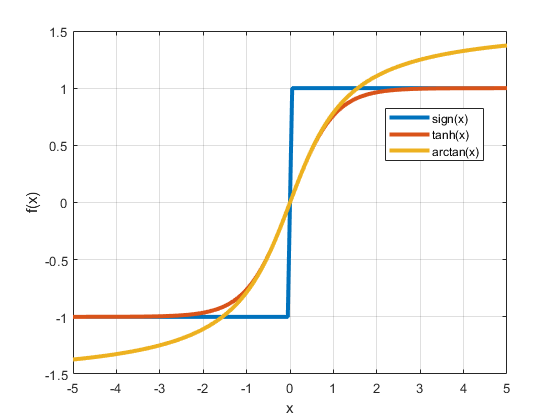

% Апроксимация нелинейной функции sign(x)
x = linspace(-5, 5);
figure();
plot(x, sign(x), "LineWidth", 3);
hold on;
plot(x, tanh(x), "LineWidth", 3);
hold on;
plot(x, atan(x), "LineWidth", 3);
grid();
legend('sign(x)', 'tanh(x)', 'arctan(x)', "Location","best");
ylabel('f(x)');
xlabel('x');

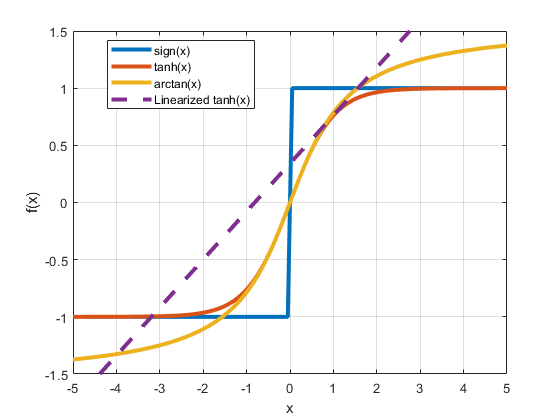

% Линеаризации функции tanh(x) по Тейлору
x_0 = 1;  % Точка линеаризации
f = tanh(x_0) + sech(x_0)^2 * (x - x_0);
plot(x, f, "LineWidth", 3, "LineStyle","--");
legend('sign(x)', 'tanh(x)', 'arctan(x)', 'Linearized tanh(x)', "Location","best");
ylabel('f(x)');
xlabel('x');
ylim([-1.5 1.5])

% Линейная модель без Кулоновского трения

% Компактная переменная: выходной ток двигателя - сила на колесе
Kmotor = Kt*l/r

Kmotor =         18.13



A = [0 0 0    1     0    0          0               0               0        % A - Матрица динамики системы
     0 0 0    0     1    0          0               0               0
     0 0 0    0     0    1          0               0               0
     0 0 0 -Bv/M    0    0 -sin(pi/3)*Kmotor/M      0      sin(pi/3)*Kmotor/M
     0 0 0    0 -Bvn/M   0  cos(pi/3)*Kmotor/M  -Kmotor/M  cos(pi/3)*Kmotor/M   
     0 0 0    0     0 -Bw/J     d*Kmotor/J      d*Kmotor/J      d*Kmotor/J
     0 0 0    0     0    0        -1/Ti             0               0
     0 0 0    0     0    0          0             -1/Ti             0
     0 0 0    0     0    0          0               0             -1/Ti];
 
B = [   0      0       0        % B - Матрица усиления входного сигнала
        0      0       0
        0      0       0
        0      0       0
        0      0       0
        0      0       0
      1/Ti     0       0
        0     1/Ti     0
        0      0      1/Ti];
 
C = [1 0 0 0 0 0 0 0 0                    % C - Матрица выходного сигнала
     0 1 0 0 0 0 0 0 0
     0 0 1 0 0 0 0 0 0
     0 0 0 1 0 0 0 0 0 
     0 0 0 0 1 0 0 0 0
     0 0 0 0 0 1 0 0 0
     0 0 0 0 0 0 1 0 0
     0 0 0 0 0 0 0 1 0
     0 0 0 0 0 0 0 0 1];
 
 D = [0 0 0                         % D - Матрица прямой связи
      0 0 0
      0 0 0
      0 0 0
      0 0 0
      0 0 0
      0 0 0
      0 0 0
      0 0 0];
 
sysC = ss(A,B,C,D,'StateName',{'X' 'Y' 'Theta' 'V' 'Vn' 'W' 'i_out_0' 'i_out_1' 'i_out_2'}, ...
    'InputName',{'I0' 'I1' 'I2'}, 'OutputName', {'X' 'Y' 'Theta' 'V' 'Vn' 'W' 'i_out_0' 'i_out_1' 'i_out_2'}');

% Дискретизация системы
Ts = 0.02;  % Time step, [c]
T_odom = 0.025;  % Time step одометрия, [c]
T_loc = 0.045;     % Time step локализация, [c]

sysD = c2d(sysC,Ts);
[Phi,Gam,Cd,Dd] = ssdata(sysD);

% Наблюдаемость системы - to be discussed

% Аугментация системы, добавление интегрирующих состояний по x, y, theta
Phi_aug = [Phi zeros(9,3)
           Cd(1:3,1:9) eye(3)];

Gam_aug = [Gam
           zeros(3,3)];

Cd_aug = [Cd zeros(9,3)
          zeros(3,9) eye(3)];

Dd_aug = zeros(12,3);

sysD_aug = ss(Phi_aug, Gam_aug, Cd_aug, Dd_aug, Ts,'StateName',{'X' 'Y' 'Theta' 'V' 'Vn' 'W' 'i_out_0' 'i_out_1' 'i_out_2' 'Int_Err_X' 'Int_Err_Y' 'Int_Err_Theta'}, ...
    'InputName',{'I0' 'I1' 'I2'}, 'OutputName', {'X' 'Y' 'Theta' 'V' 'Vn' 'W' 'i_out_0' 'i_out_1' 'i_out_2' 'Int_Err_X' 'Int_Err_Y' 'Int_Err_Theta'}');

% Управляемость системы
Wc = ctrb(Phi_aug, Gam_aug);
if rank(Wc) == length(Phi_aug)
    disp('The system is controllable!');
else 
    disp('The system is not controllable!');
end

The system is controllable!



% Синтез LQR контроллера
% Задание максимальных отклонений по параметрам
% Динамика системы
m_x = 0.0001;         % [м]
m_y = 0.0001;         % [м]
m_th = deg2rad(0.03);  % [рад]
m_v = 0.05;         % [м/с] m_v = 0.0001;
m_vn = 0.05;        % [м/с]
m_w = 0.05;         % [м/с]
m_i = 0.01;
m_err_x = 0.002;       
m_err_y = 0.002;
m_err_th = 0.005;
% Управление системы
u_f = 0.002;         % [H]

Q = diag([1/m_x^2 1/m_y^2 1/m_th^2 1/m_v^2 1/m_vn^2 1/m_w^2 1/m_i^2 1/m_i^2 1/m_i^2 1/m_err_x^2 1/m_err_y^2 1/m_err_th^2]);

R = diag([1/u_f^2 1/u_f^2 1/u_f^2]);

[K_aug, S, e] = dlqr(Phi_aug, Gam_aug, Q, R);

% Разделим контроллер на две части
K_fsfb = K_aug(1:3, 1:9);           % Feedback part
K_int = K_aug(1:3, 10:12);             % Integral part

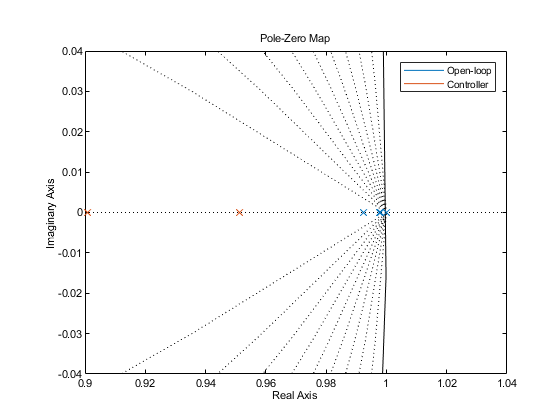

% Анализ динамики и стабильности системы
% Корни замкнутой системы с контроллером
Eig = eig(Phi_aug - Gam_aug*K_aug);        
% Корневой годограф
figure('Name', 'Poles of the systems');
opt = pzoptions;
opt.Grid = 'on';
opt.IOGrouping = 'all';
opt.Xlim = [0.9 1.04];
opt.Ylim = [-0.04 0.04];
pzplot(sysD_aug, feedback(sysD_aug,K_aug), opt);
legend('Open-loop','Controller');

% Kalman estimator
C_meas = Cd(1:6, :);
D_meas = zeros(6, 3);
sysD_meas =  ss(Phi, Gam, C_meas, D_meas, Ts,'StateName',{'X' 'Y' 'Theta' 'V' 'Vn' 'W' 'i_out_0' 'i_out_1' 'i_out_2'}, ...
    'InputName',{'I0' 'I1' 'I2'}, 'OutputName', {'X' 'Y' 'Theta' 'V' 'Vn' 'W'}');

% Hypothesis on noise covariances
Qn = diag([0.5 0.5 0.5]);  % Process noise
Rn = diag([0.01 0.01 0.01 1 1 1]);

[kest, L, P] = kalman(sysD_meas,Qn,Rn);
poles = (eig(Phi-L*C_meas)).^10;
L_kal = place(Phi',Cd',poles).';

% Save controllers for ROS
csvwrite('C:\Users\User\OneDrive\Учеба\Skoltech\Control Systems Engineering\Project\ROS\omni_dynamic_controller\scripts\K_fsfb.csv',K_fsfb)
csvwrite('C:\Users\User\OneDrive\Учеба\Skoltech\Control Systems Engineering\Project\ROS\omni_dynamic_controller\scripts\K_int.csv',K_int)